# Birds at risk

Determine how many birds are at risk of collision with windturbine where and when.

## Load data

Load windfarm data which has been processed (`windfram_processing.mlx`)

load('data/windfarms_processed.mat')

Load the grid of the bird density estimation

load('../2018/data/Density_estimationMap','g');

Load flow estimation (density and speed)

load('../2018/data/Density_estimationMap','gd');
load('../2018/data/Flight_estimationMap','guv');

Load the ratio map of altiudinal distribution of the bird

load('./data/ratio');
%g_ratio = 0.05;

## Compute Bird at Risk

## Construct turbine sweep area map

[G,ID] = findgroups(tim.grid_id);
turbineSweptArea=nan(1,g.nlm);
turbineSweptArea(ID) = splitapply(@nansum,tim.turbine_sweptArea.*tim.Number_of_turbines,G);
turbineSweptAreaMap = nan(size(g.latlonmask));
turbineSweptAreaMap(g.latlonmask) = turbineSweptArea;

Display data

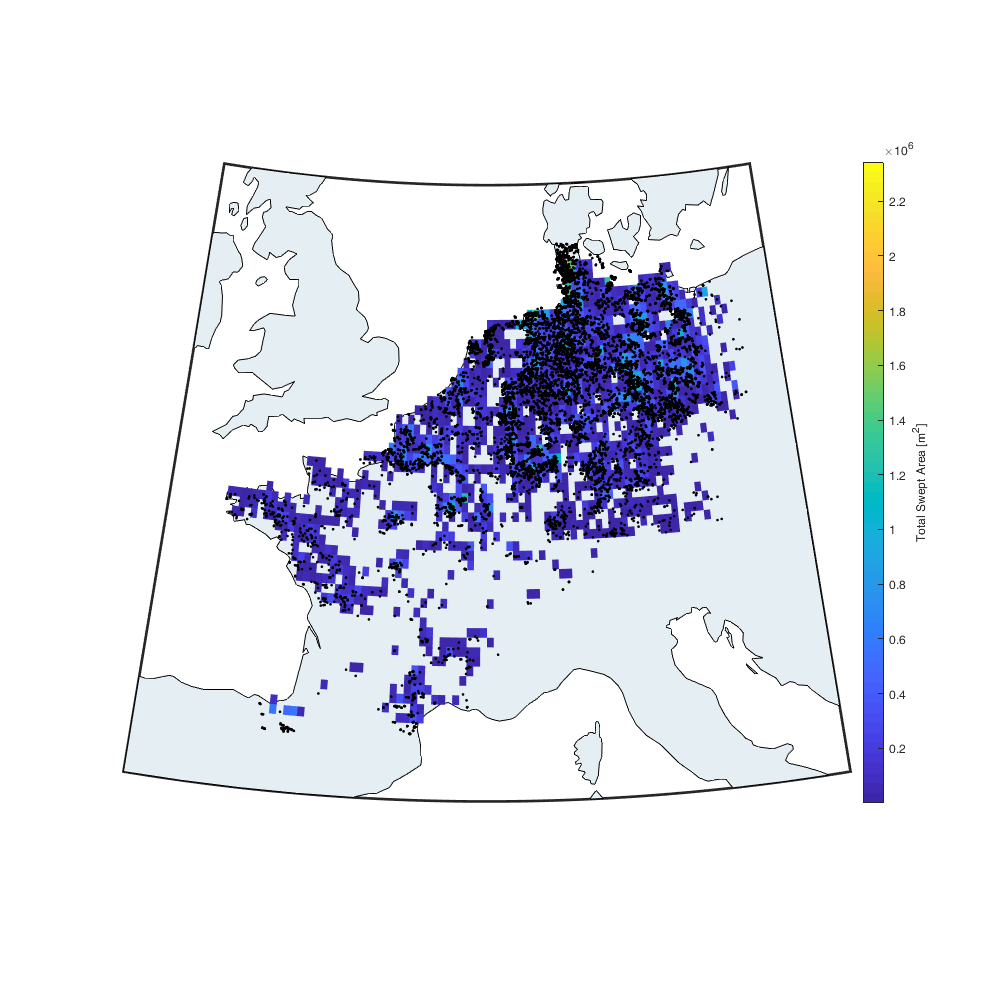

figure('position',[0 0 1000 1000]); hold on;
h = worldmap([g.lat(1)-2 g.lat(end)+2], [g.lon(1)-2 g.lon(end)+2]);
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
geoshow('landareas.shp', 'FaceColor', [228 238 243]./255);
surfm(g.lat,g.lon,turbineSweptAreaMap)
scatterm(tim.Latitude,tim.Longitude,'.k');
c=colorbar; c.Label.String='Total Swept Area [m^2]';

## Bird at Risk

Compute the bird at risk as


$$A_{\textrm{swept}} {\cdot N}_{\textrm{wt}} \cdot \rho \cdot r_{\textrm{wt}} \cdot h\cdot v$$


- $N_{\textrm{wt}} \cdot A_{\textrm{swept}}$: Swept area map (sum of swept are of windturbine in each grid cell) [m^2]

- $\rho$ : bird density [bird/km^2]

- $r_{\textrm{wt}}$: ratio of bird density (in bird/km^2) at windturbine elevation [-]

- $h$: height assumed when computing the ratio. []

- $v=\sqrt{v_u^2 +v_u^{2\;} }$: bird speed [m/s]

birdAtRisk = nan(g.nlat,g.nlon,g.nt);
birdAtRisk(repmat(g.latlonmask,1,1,g.nt)) = (turbineSweptArea' .* gd.dens_est * 1e-6 .* g_ratio / (windturbine_maxheight-windturbine_minheight)  .* sqrt(guv.u_est.^2 + guv.v_est.^2)*60*60); 
% m^2 * bird/km^2 * km^2/m^2 * - * 1/m * m/s * s/hr -> bird/hr
% m^2 * bird/m^2 * 1/m * m/hr -> bird/hr

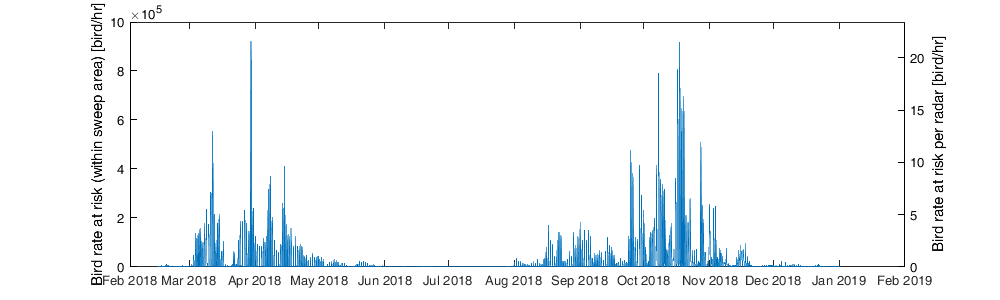

figure('position',[0 0 1000 300]); 
plot(g.time,reshape(nansum(nansum(birdAtRisk,1),2),1,[]));
ylim([0 1e6]);ylabel('Bird rate at risk (within sweep area) [bird/hr]')
yyaxis 'right'
ax = gca; ax.YAxis(2).Color = 'k';
ylim([0 1e6]/nansum(tim.Number_of_turbines)); ylabel('Bird rate at risk per radar [bird/hr]')

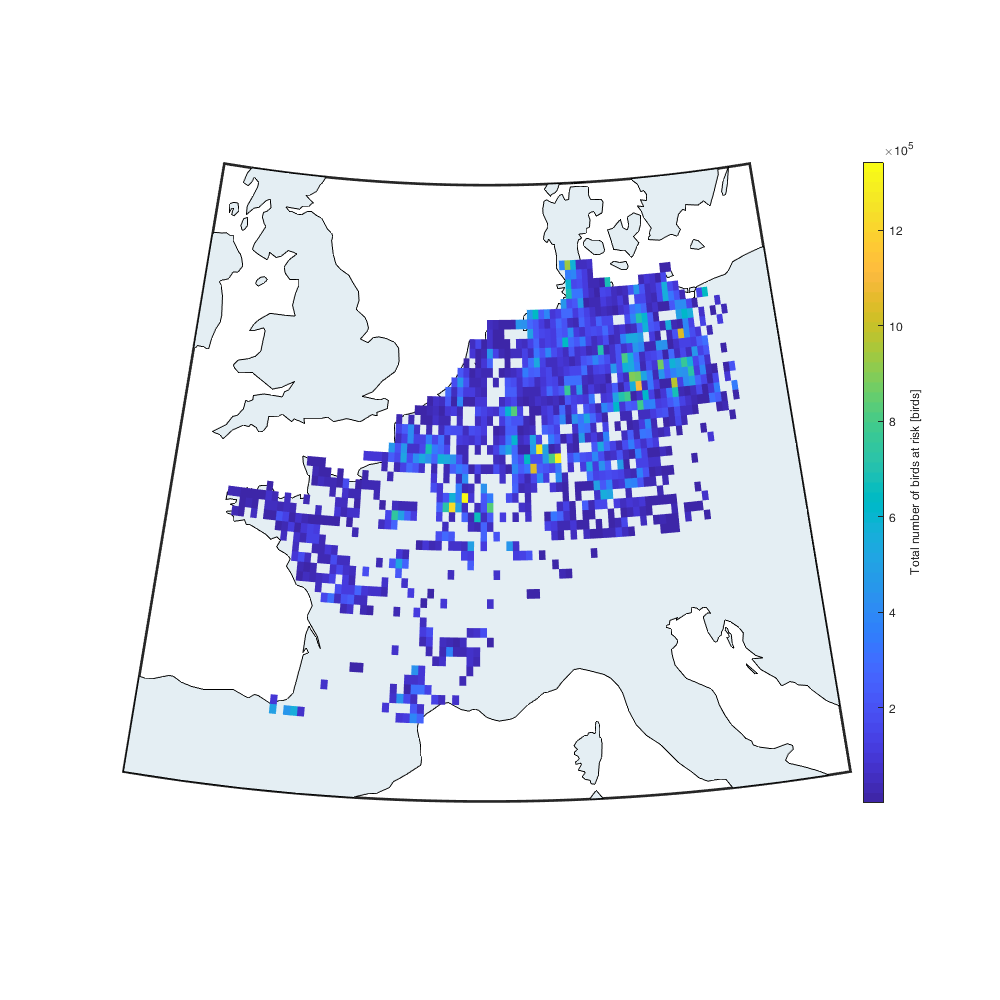

figure('position',[0 0 1000 1000]); hold on;
h = worldmap([g.lat(1)-2 g.lat(end)+2], [g.lon(1)-2 g.lon(end)+2]);
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
geoshow('landareas.shp', 'FaceColor', [228 238 243]./255);
tmp =nansum(birdAtRisk/4,3); % /4 to convert birds/hr -> birds (resolution of 15min)
tmp(tmp==0)=nan;
surfm(g.lat,g.lon,tmp)
%scatterm(tim.Latitude,tim.Longitude,'.k');
c=colorbar; c.Label.String='Total number of birds at risk [birds]';

## Simulated Bird density

Run on UNIL server

% rar = nan(g.nt,500);

prepare the birdrisk template (just need to multiply by density

% birdAtRisk_t = nan(g.nlat,g.nlon,g.nt);
% birdAtRisk_t(repmat(g.latlonmask,1,1,g.nt)) = turbineSweptArea' * 1e-6 .* g_ratio / (windturbine_maxheight-windturbine_minheight)  .* sqrt(guv.u_estim.^2 + guv.v_estim.^2)*60*60; 

Loop through all files

% for ii=1:5
%     load(['D:\Guests\rafnuss_at_gmail_com\tmp_BMM2018\Density_simulationMap_reassemble_' num2str(ii)]);
%     for i_real = 1:size(real_dens,4)
%         rar(:, (ii-1)*100+i_real) = reshape(nansum(nansum(birdAtRisk_t .* real_dens(:,:,:,i_real),1),2),1,[]);
%     end
% end

Save

% save('data/BirdAtRisk_sim','rar')

Load

load('data/BirdAtRisk_sim')

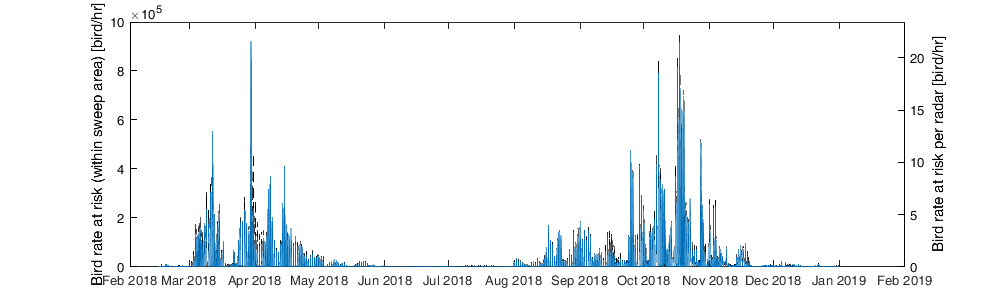

figure('position',[0 0 1000 300]);  hold on;
plot(g.time,nanmean(rar,2),'k')
plot(g.time,quantile(rar,.1,2),'--k')
plot(g.time,quantile(rar,.9,2),'--k')
plot(g.time,reshape(nansum(nansum(birdAtRisk,1),2),1,[]),'LineWidth',0.1);

ylim([0 1e6]);ylabel('Bird rate at risk (within sweep area) [bird/hr]')
yyaxis 'right'
ax = gca; ax.YAxis(2).Color = 'k'; box on
ylim([0 1e6]/nansum(tim.Number_of_turbines)); ylabel('Bird rate at risk per radar [bird/hr]')

Convert time resolution of birdAtRisk to match energy map

[~,Locb]=ismember(dateshift(g.time,'end','hour'),time);
birdAtRisk_map = nan(size(birdAtRisk,1),size(birdAtRisk,2),numel(time));
for i=1:numel(time)
    birdAtRisk_map(:,:,i) = nanmean(birdAtRisk(:,:,Locb==i),3);
end

## Compute Power Production

Put the power on a grid

tmp=nan(g.nlm,numel(time));
tmp2=nan(g.nlm,numel(time));
for i_ll=1:g.nlm
    id = tim.grid_id==i_ll;
    tmp(i_ll,:) = nansum(power(id,:));
    tmp2(i_ll,:) = nansum(tim.Number_of_turbines(id));
    % tmp(i_ll,:) = nansum(max(tim.powerCurve(id,:),[],2).*tim.Number_of_turbines(id));
end
power_map=nan(g.nlat,g.nlon,numel(time));
power_map(repmat(g.latlonmask,1,1,numel(time))) = tmp;
nb_turb_map=nan(g.nlat,g.nlon,numel(time));
nb_turb_map(repmat(g.latlonmask,1,1,numel(time))) = tmp2;

Plot

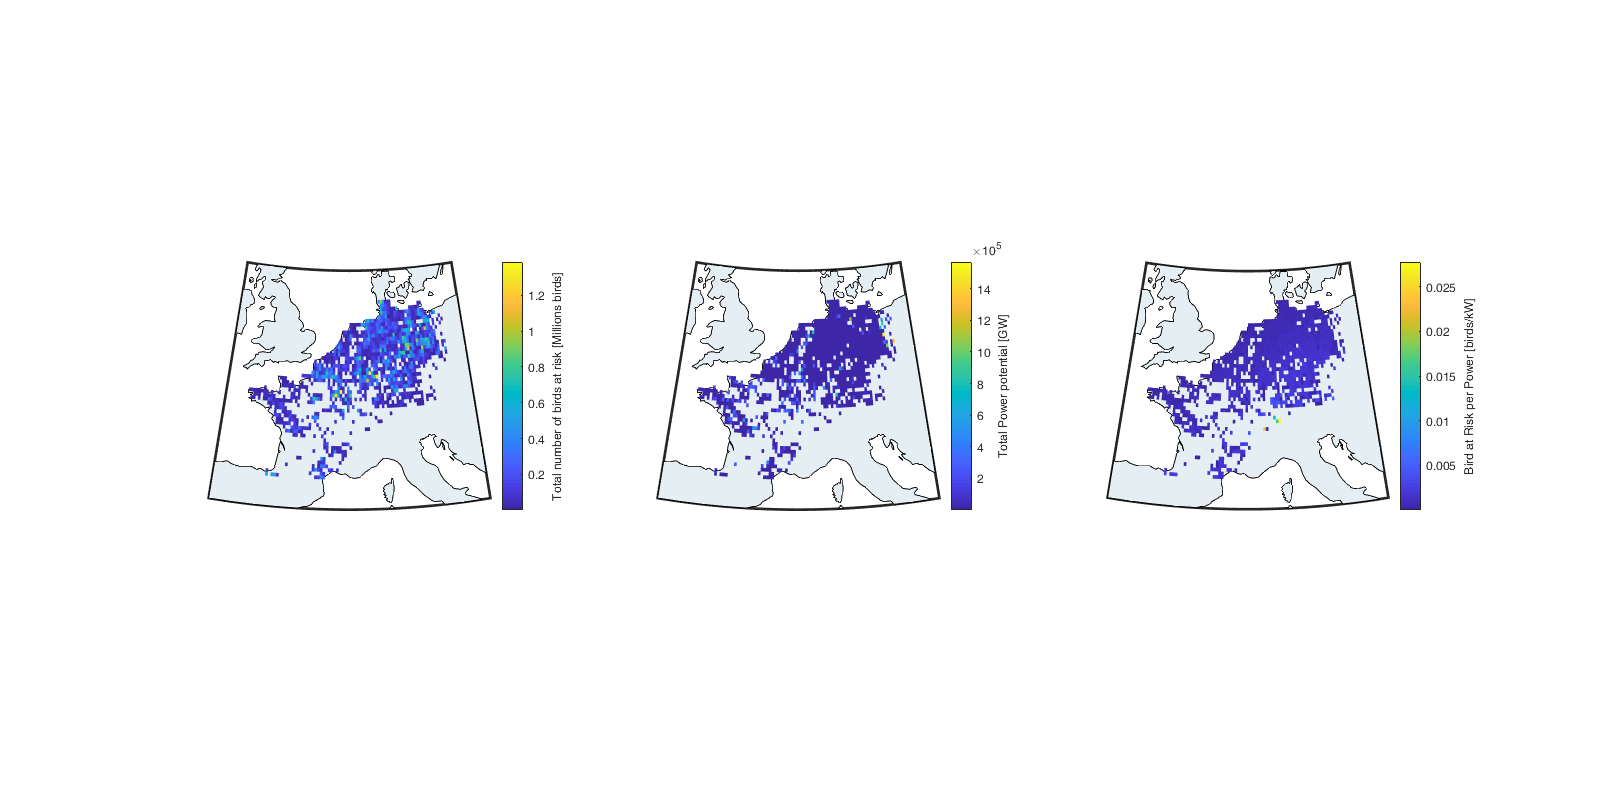

figure('position',[0 0 1600 800]); 
subplot(1,3,1); hold on;
h = worldmap([g.lat(1)-2 g.lat(end)+2], [g.lon(1)-2 g.lon(end)+2]);
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
geoshow('landareas.shp', 'FaceColor', [228 238 243]./255);
tmp = nansum(birdAtRisk_map,3); % /4 to convert birds/hr -> birds (resolution of 15min)
tmp(tmp==0)=nan; 
surfm(g.lat,g.lon,tmp/1e6)
%scatterm(tim.Latitude,tim.Longitude,'.k');
c=colorbar; c.Label.String='Total number of birds at risk [Millions birds]';

subplot(1,3,2); hold on;
h = worldmap([g.lat(1)-2 g.lat(end)+2], [g.lon(1)-2 g.lon(end)+2]);
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
geoshow('landareas.shp', 'FaceColor', [228 238 243]./255);
tmp = nansum(power_map,3); % /4 to convert birds/hr -> birds (resolution of 15min)
tmp(tmp==0)=nan; 
surfm(g.lat,g.lon,(tmp/1e6))
%scatterm(tim.Latitude,tim.Longitude,'.k');
c=colorbar; c.Label.String='Total Power potential [GW]';

subplot(1,3,3); hold on;
h = worldmap([g.lat(1)-2 g.lat(end)+2], [g.lon(1)-2 g.lon(end)+2]);
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
geoshow('landareas.shp', 'FaceColor', [228 238 243]./255);
tmp = nansum(birdAtRisk_map,3)./nansum(power_map,3); % /4 to convert birds/hr -> birds (resolution of 15min)
tmp(tmp==0)=nan; 
surfm(g.lat,g.lon,(tmp))
%scatterm(tim.Latitude,tim.Longitude,'.k');
c=colorbar; c.Label.String='Bird at Risk per Power [birds/kW]';

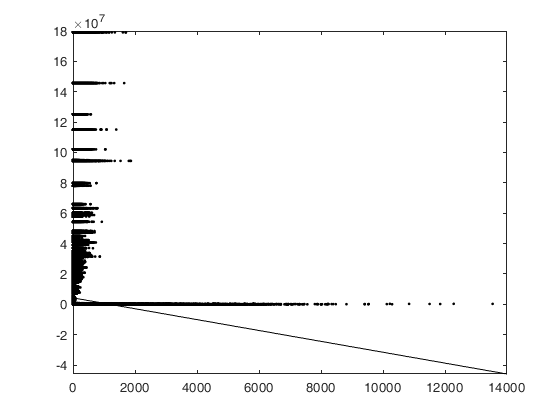

figure; plot(birdAtRisk_map(:),power_map(:),'.k'); l=lsline;

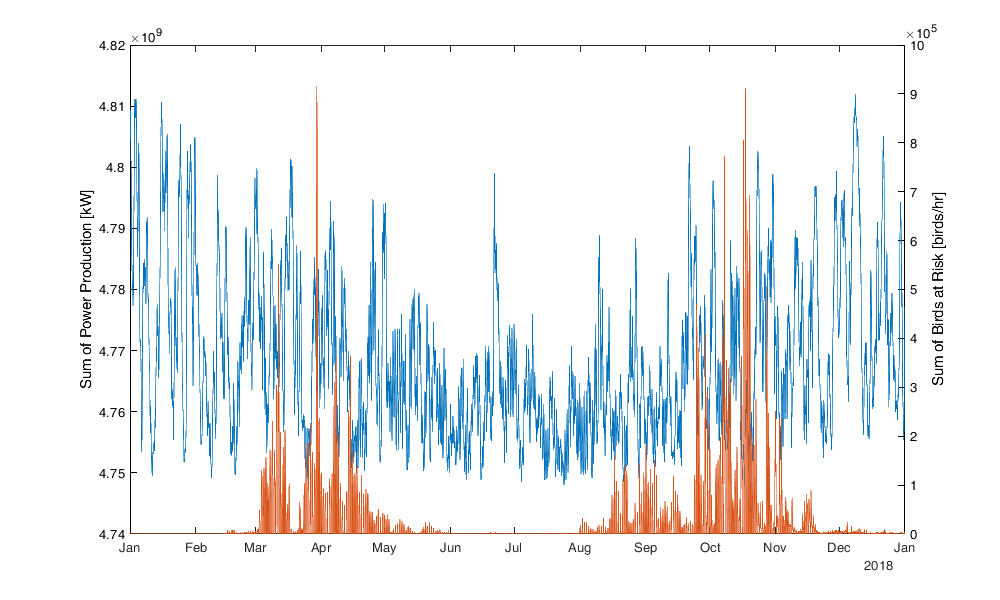

figure('position',[0 0 1000 600]); 
plot(time,reshape(nansum(nansum(power_map,1),2),1,[]))
ylabel('Sum of Power Production [kW]')
yyaxis right
plot(time,reshape(nansum(nansum(birdAtRisk_map,1),2),1,[]))
ylabel('Sum of Birds at Risk [birds/hr]')
ax = gca; ax.YAxis(1).Color = 'k'; ax.YAxis(2).Color = 'k';

## Save

save('data/birdAtRisk.mat','birdAtRisk');